# Boolean Optimal Causation Entropy

In this supplementary document, we provide a user guide and hands-on examples for using the Boolean oCSE (BoCSE) MATLAB code. For the algorithm details, citation, and more details, the user can refer for our published work: 

- Jie Sun, Abd AlRahman AlMomani, Erik Bollt. "*Data-Driven Learning of Boolean Networks and Functions by Optimal Causation Entropy Principle (BoCSE)*". ??????

## Reading raw data

We start with reading the raw data. We consider here the example from our paper on Risk Causality Analysis of Loans in Default Status.

We consider the open dataset from LendingClub (American peer-to-peer lending company), which can be downloaded from [LendingClub](https://www.lendingclub.com/statistics/additional-statistics?) website. We considered the dataset for the year 2019 (four quarters). The data for each quarter is stored in separate csv file, then we start by reading and stack the target variables from the seperate files as the following: 

clearvars; close all; clc;

rng(1)

addpath("Raw Data/")

name = {'2019Q1.csv','2019Q2.csv','2019Q3.csv','2019Q4.csv'}; %csv files names list

T = [];
for i=1:length(name)

    options = detectImportOptions(name{i});
    
    % Now, we provide the variables we want to read to the options
    % structure
    options.SelectedVariableNames = {'loan_status',...
                                    'home_ownership',...
                                    'delinq_2yrs',...
                                    'verification_status',...
                                    'pub_rec',...
                                    'application_type',...
                                    'num_accts_ever_120_pd',...
                                    'num_tl_op_past_12m',...
                                    'pub_rec_bankruptcies',...
                                    'funded_amnt',...
                                    'annual_inc',...
                                    'term'};

    % Reading the specified variables
    L = readtable(name{i},options);
    
    ix = cellfun(@strcmp,L.loan_status,repmat({'Current'},length(L.loan_status),1));
    L(ix,:) = [];
    
    T = cat(1,T,L);

end


The dataset contains more than 500,000 entries (data points, sample size). However, we only considered the long term (the final) status of the loans.  Therefore,  we excluded all the loans with the status **``Current**'' as an outcome (we did that in line#30-31 in the code block above), to have a sample size of 62,460 for our analysis. That is, all can be classified to and outcome **``Paid in full'**', or **``Default'' **status. We should emphasize here that we only considered the parameters as Boolean in nature, which limits the considered  to those 10 parameters (line#14 in the code block above) that we investigate as to their influence on the outcomes.

## Data to Boolean variables conversion

In the following, we cast the variables to put them all in boolean form. First, we construct the Boolean vector that represent the outcomes (output) $Y$. Simply, since the loan status variable has only one of two states (**``Paid in full'**', or **``Default''), **we can say that $Y=1$                                            if loan_status is 'Fully Paid', and $Y=0$ otherwise.

N = size(T,1);
% Output Y (fully paid or not)
Y = cellfun(@strcmp,T.loan_status,repmat({'Fully Paid'},N,1));

Table 3 shows the attributes and their description. In loan issuing risk analysis, the amount of the requested loan and the annual income of the borrower are important variables to consider, and they are both numeric variables. We introduce here the combined attribute, loan to income ratio, which combines both variables in the form of a Boolean variable. Our dataset has a sample size of 62,460, and the loan to income ratio range from 0.0001 to 36000. So, we considered the median value $\mu \approx 0.2$ to be our threshold step, such that $X_9 = 0$, indicate that the loan to income ratio of the loan request is less than $0.2$, and it is within the lowest 50% of all the requested loans over the period (which is in our case, one year).

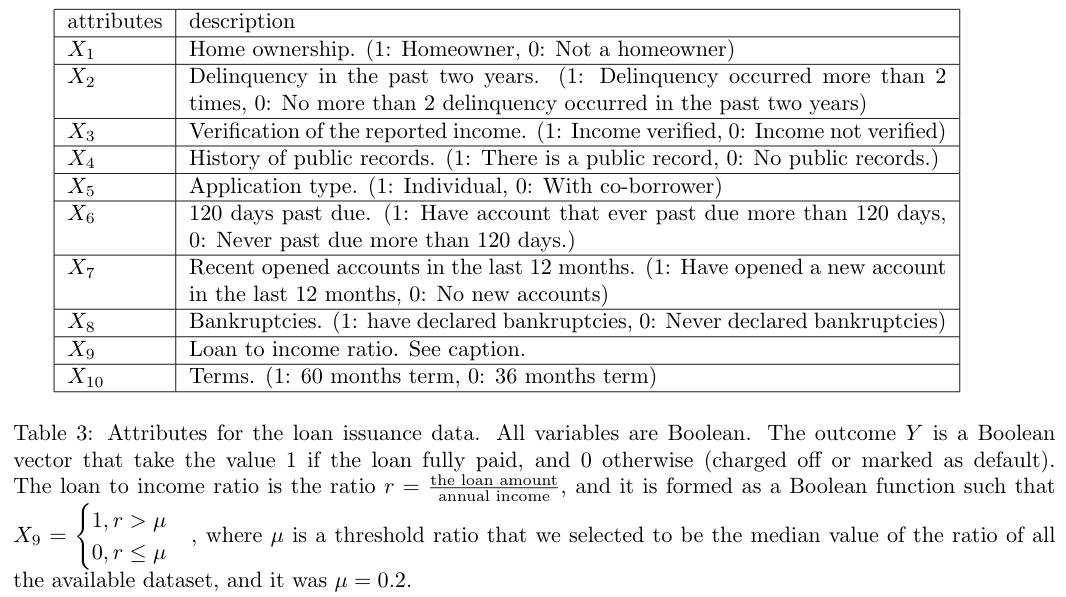


% X1: Home Ownership
X = cellfun(@strcmp,T.home_ownership,repmat({'OWN'},N,1));

% X2: delinq_2yrs
t = T.delinq_2yrs>2;
X = cat(2,X,t);


% X3: verification_status
t = cellfun(@strcmp,T.verification_status,repmat({'Verified'},N,1));
X = cat(2,X,t);



% X4: pub_rec
t = ~~T.pub_rec;
X = cat(2,X,t);

% X5: application_type
t = cellfun(@strcmp,T.application_type,repmat({'Individual'},N,1));
X = cat(2,X,t);

% X6: num_accts_ever_120_pd
t = ~~T.num_accts_ever_120_pd;
X = cat(2,X,t);

% X7: num_tl_op_past_12m
t = ~~T.num_tl_op_past_12m;
X = cat(2,X,t);

% X8: pub_rec_bankruptcies
t = ~~T.pub_rec_bankruptcies;
X = cat(2,X,t);

% X9: loan to income ratio
t = T.funded_amnt./T.annual_inc;
X = cat(2,X,t>median(t));

% X10: Term
t = cellfun(@strcmp,T.term,repmat({'60 months'},N,1));
X = cat(2,X,t);

## BoCSE Call

The syntax for calling the BoCSE with the default setting is:

[index, Table] = BoCSE(Y,X);

where it return two variables:

- index: a Boolean vector represent a relevance flag of columns of $X$. $index_i=$ true, if the $i^{th}$ column of $X$ is relevent, and $index_i=$ false otherwise. The indices of the minimal set of Boolean functions based on BoCSE is indicated by the vector:

disp(index)

   0   0   1   0   0   0   0   0   1   1



- Table: A detailed table of the states, outcome, and probability of occurence for each state-outcome combination:

disp(Table)

    X3    X9    X10    Probability Y=0    Probability Y=1
    __    __    ___    _______________    _______________

    0     0      0         0.24836            0.75164    
    0     0      1         0.33667            0.66333    
    0     1      0         0.34837            0.65163    
    0     1      1         0.39923            0.60077    
    1     0      0         0.31724            0.68276    
    1     0      1         0.38599            0.61401    
    1     1      0         0.41463            0.58537    
    1     1      1         0.46288            0.53712    



## Robustness to Noise

The example we show above is inhiretily stochastic, similar to the other examples introduced in our paper.

However, to further investigate the effect of noise, we introduce the following two examples:

### Example 1: Noise Effect

For the stochatic system shown above, and in order to further investigate the effect of noise, we consider the result obtained from the BoCSE as the ground truth, and we add more noise to the system to see how the results change under this additional noise. 

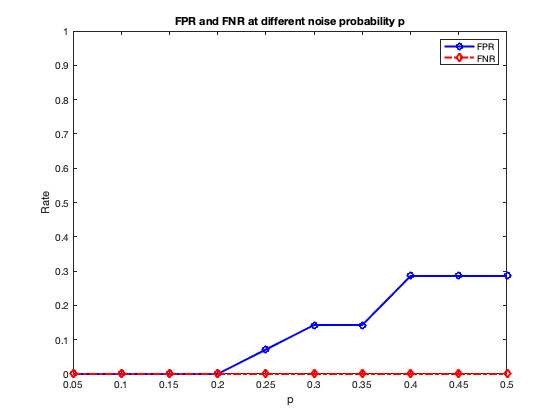

p = 0.05:0.05:0.5;
Runs = 10;

groundTruth = index;
totalSolutions = [];
for r=1:Runs
    for i=1:length(p)
        randix = (rand(size(Y))<p(i));
        Ynoisy = Y;
        Ynoisy(randix) = randi([0 1],sum(randix),1);
        
        ix = BoCSE(Ynoisy,X);
        
        totalSolutions = cat(1,totalSolutions, ix);
    end
end

FP  = bsxfun(@and,~totalSolutions , groundTruth);
FPR = sum(FP,2)./sum(~groundTruth);
FPR = reshape(FPR,length(p),Runs);
FPR = median(FPR,2);

FN  = bsxfun(@and,totalSolutions , ~groundTruth);
FNR = sum(FN,2)./sum(groundTruth);
FNR = reshape(FNR,length(p),Runs);
FNR = median(FNR,2);

figure
plot(p(:),FPR,'-ob','LineWidth',2)
hold on
plot(p(:),FNR,'-.dr','LineWidth',2)
legend('FPR','FNR')
xlabel('p')


ylabel('Rate')
title('FPR and FNR at different noise probability p')


ylim([0 1])

### Example 2: Noise effect with deterministic Boolean function

In this example, we introduce a determistic Boolean function, and investigate the performance of BoCSE.

Consider the Boolean data matrix $X\in\mathbb{R}^{5000\times 10}$, and the outcome $Y\in\mathbb{R}^{5000\times 1}$ that is given by:


$$Y = (X_2 \cdot X_4) + X_6$$


(read as ($X_2$ AND $X_4$) OR $X_6$). This data can be created by the following:

clearvars; 

X = randi([0 1],300,20);

Y = (X(:,2)&X(:,4)) | X(:,6);

Now, we see the result of BoCSE for this determistic system:


[index, Table] = BoCSE(Y,X);
index

index = 1×20 logical array
   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0



Table

Table = 8×5 table
    X2    X4    X6    Probability Y=0    Probability Y=1
    __    __    __    _______________    _______________

    0     0     0            1                  0       
    0     0     1            0                  1       
    0     1     0            1                  0       
    0     1     1            0                  1       
    1     0     0            1                  0       
    1     0     1            0                  1       
    1     1     0            0                  1       
    1     1     1            0                  1       


We see that BoCSE detected the exact variables that govern the underlying Boolean function. Moreover, BoCSE shows high robustness to noise, as we show in the following. Similar to the previous example, we test the BoCSE performance under different levels of noise that goverened by Bernoulli probability $p$:

p = 0.2:0.1:1;
Runs = 10;
tic
groundTruth = [0 1 0 1 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
totalSolutions = [];
for r=1:Runs
    for i=1:length(p)
        randix = (rand(size(Y))<p(i));
        Ynoisy = Y;
        Ynoisy(randix) = randi([0 1],sum(randix),1);
        
        ix = BoCSE(Ynoisy,X);
        
        totalSolutions = cat(1,totalSolutions, ix);
    end
end

FP  = bsxfun(@and,~totalSolutions , groundTruth);
FPR = sum(FP,2)./sum(~groundTruth);
FPR = reshape(FPR,length(p),Runs);
FPR = median(FPR,2);

FN  = bsxfun(@and,totalSolutions , ~groundTruth);
FNR = sum(FN,2)./sum(groundTruth);
FNR = reshape(FNR,length(p),Runs);
FNR = median(FNR,2);

figure
plot(p(:),FPR,'-ob','LineWidth',2)
hold on
plot(p(:),FNR,'-.dr','LineWidth',2)
legend('FPR','FNR')
xlabel('p')

time = toc

time = 62.4977

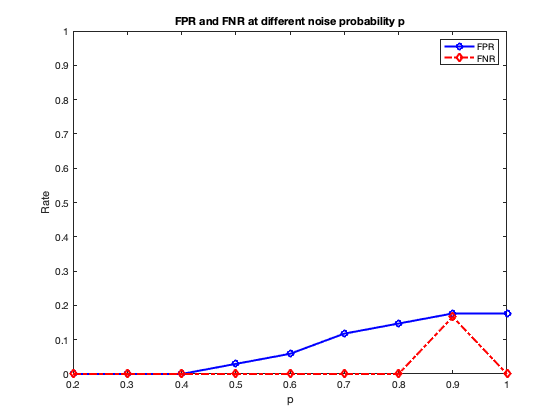

ylabel('Rate')
title('FPR and FNR at different noise probability p')


ylim([0 1])